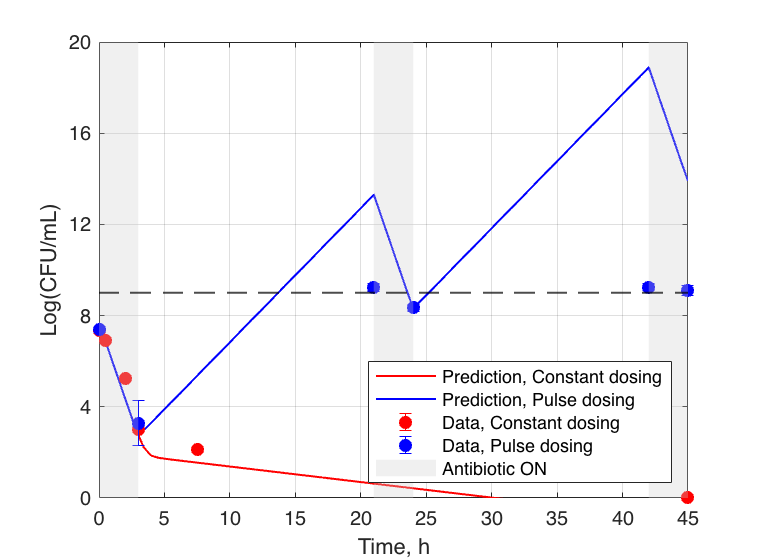

clear all
clc
close all

% Import experimental data 
load('Validation_Exp_02.mat');
xdata =time;
ydata =N;
error = err;


set(gcf,'position',[150,150,380,280])



N0 = 7.7;

% Paramter values estimated from Figure 6
f0 = 9.5e-7;
k1 = [-.15698 -3.8498  5e-06 0]; % [Kp_on Kn_on a_on b_on]
k2 = [-1.1598 1.354  0 1.1598]; % [Kp_off Kn_off a_off b_off]
T_on = [3];
ratio = [  6]; % t_off/t_on, T_off = T_on*ratio

m = length(T_on);
n = length(ratio);
I = m*n;
counter = 1;
for j = 1:n
    for i = 1: m
       
            t_on = T_on(i);
            t_off = T_on*ratio(j);
            t_start = 0;
            t_stop = t_on;
            t_total = 45;

            tspan = linspace(t_start,t_stop,20);
            [t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,10.^N0*[(1-f0),f0]);
            tplot = tspan;
            y_model = log10(sum(Ns,2));
            
            while t_stop < t_total
            t_start = t_stop;
            t_stop = t_start+t_off;
            if t_stop > t_total
                t_stop = t_total;
            end
            tspan = linspace(t_start,t_stop,30);
            [t,Ns] = ode45(@(t,y)odeint(t,y,k2),tspan,[Ns(end,1), Ns(end,2)]);
            tplot = [tplot,tspan];
            y_model = [y_model;log10(sum(Ns,2))]; 
            
            if t_stop < t_total
                t_start = t_stop;
                t_stop = t_start+t_on;
                if t_stop > t_total
                    t_stop = t_total;
                end
                tspan = linspace(t_start, t_stop, 30);
                [t,Ns] = ode45(@(t,y)odeint(t,y,k1),tspan,[Ns(end,1), Ns(end,2)]);
                tplot = [tplot,tspan];
                y_model = [y_model;log10(sum(Ns,2))];
            
            end
            end
            t_stop = t_total;
            t_start = t_stop;
            
            [tc,yc] = ode45(@(t,y)odeint(t,y,k1),linspace(0,t_total,80),10.^N0*[(1-f0),f0]);

            subplot(m,n,counter)
            counter = counter + 1;
            plot(tc, log10(sum(yc,2)), 'r-', 'LineWidth',1)
            hold on

            plot(tplot', y_model, 'b-', 'LineWidth',1)
          
            
            ylabel('Log(CFU/mL)');
            xlabel('Time, h');
%             legend('Pulse (sim)','Control_{sim}', 'Pulse_{data}', 'Control_{data}',location='best')
            str = sprintf('t_{on} = %.2f , t_{off} = %.2f*t_{on}', t_on, ratio(j));
%             title(str);
            xlim([0 t_total])
            ylim([0 20])
            hold off
            grid on
        
    end 
end

hold on 

errorbar(xdata(1:6,1),ydata(1:6,1),error(1:6,1), 'ro', 'MarkerFaceColor','r')
hold on
errorbar(xdata(7:end,1),ydata(7:end,1), error(7:end,1),'bo', 'MarkerFaceColor', 'b')



x1 = [0 3 3 0];
y1 = [-2 -2 20 20];
x2 = [21 24 24 21];
y2 = [-2 -2 20 20];
x3 = [42 45 45 42];
y3 = [-2 -2 20 20];
patch(x1,y1, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x2,y2, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);
patch(x3, y3, [0.8 0.8 0.8], 'LineStyle', 'none', 'FaceAlpha', 0.3);

hold on 

yline(9, 'k--', 'LineWidth',1)
hold off
ticks = linspace(0,20,6);
yticks(ticks)
legend('Prediction, Constant dosing','Prediction, Pulse dosing','Data, Constant dosing', 'Data, Pulse dosing', 'Antibiotic ON', Location ='southeast' )

function [dydt] = odeint(t,y,k)
dydt=zeros(2,1);
K_p=k(1);
K_n=k(2);
a=k(3);
b=k(4);
dydt(1)= K_n*y(1)+b*y(2);
dydt(2)= a*y(1)+ K_p*y(2);
end

% ode integration

